 绘制手动修改前的MUST图

绘制了每个ST的MUAP（调用plotMUAP_main）

clearvars -except ;
close all 
% M=1;L=1;T=2;
% loadfile=['E:\Result\327\13一组24一组\CKC\KYM_M' num2str(M) 'L' num2str(L) 'T' num2str(T) '_decomposed_CKC_comb111.mat'];
% load(loadfile);

load("Z:\Result\24-10-12iEMG-sEMG\xEMG_CKC.mat")

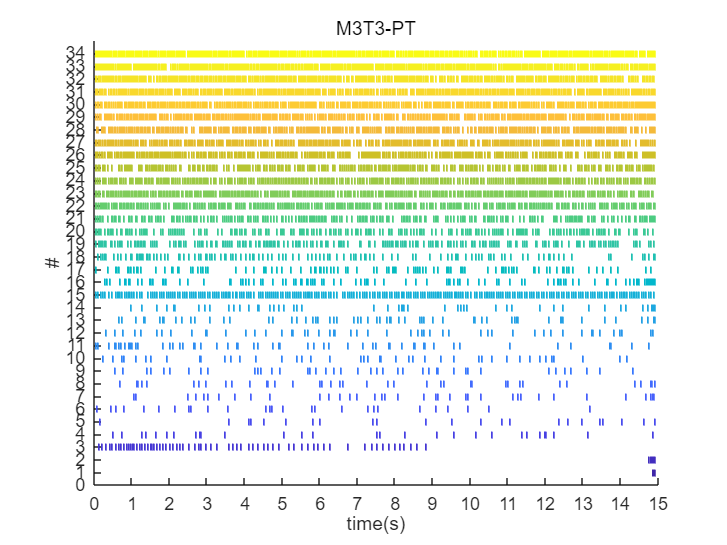

addpath 'Z:\code\MUAP_PT可视化相关'

M=1;
level=3;
trial=3;
decomps=0;
% datafilt=CKCdecomp{level,trial}.datafilt;

%%%将muapt赋予到old中
decomps=CKCdecomp{level,trial};%CKC
old=decomps.MUPulses;          %CKC



% old=CBSSdecomp{level,trial};%CBSS

% old=origin{level,trial};%原版CKC

%放电频率
fsamp=2048;

% 绘制反解得到的原始muapt
numPT=length(old); %which2show调用
clf;
pic=draw_PluseTime(old,fsamp,1);
% tn4PT=['M' num2str(M) 'L' num2str(level) 'T' num2str(trial) '-PT'];
tn4PT=['M' num2str(level) 'T' num2str(trial) '-PT'];
title(tn4PT);

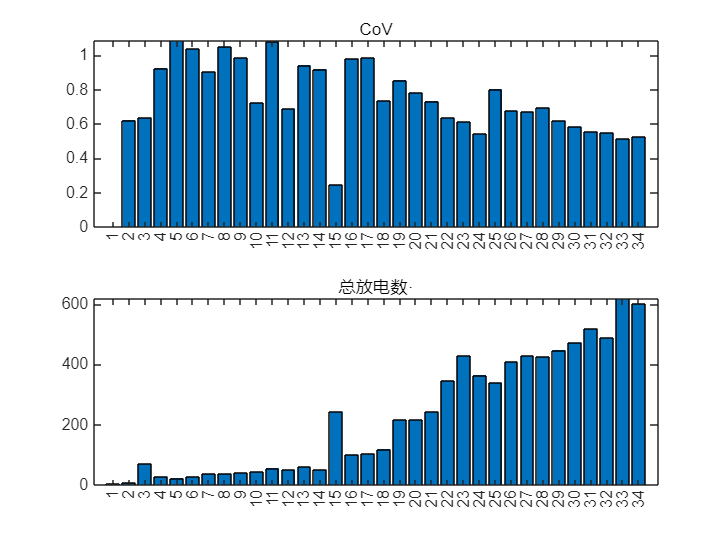


%计算muap
datafilt=decomps.datafilt;
[sigcell]=sig2cell(datafilt,6);%对5*13数据
[muaparray,~]=muapExtraction(sigcell,old,100,'STA');
%run getMUAP_main

CoV=[];
Freq=[];
%计算CoV和放电次数
for i = 1:length(old)
    isi{i}=diff(old{i});
    idx=find(isi{i}>mean(isi{i})+5*std(isi{i}));
    isi{i} = isi{i}(~ismember(1:numel(isi{i}), idx));
    CoV(i)=std(isi{i})/mean(isi{i});
    Freq(i)=length(old{i});
end
figure;
subplot(2,1,1);bar(CoV);title('CoV');xticks([1:1:numPT]);
subplot(2,1,2);bar(Freq);title('总放电数·');xticks([1:1:numPT]);

% subplot(3,1,3);bar(decomps.PNRs);
A=find(decomps.PNRs<20)

A =     32    33


B=find(CoV>0.7)

B =      4     5     6     7     8     9    10    11    13    14    16    17    18    19    20    21    25


C=find(Freq>525)

C =     33    34


D=find(Freq<10)

D =      1     2


unwant=union(union(A,B),union(C,D))

unwant =      1     2     4     5     6     7     8     9    10    11    13    14    16    17    18    19    20    21    25    32    33    34


调看每个PCA降维前后的MUAP

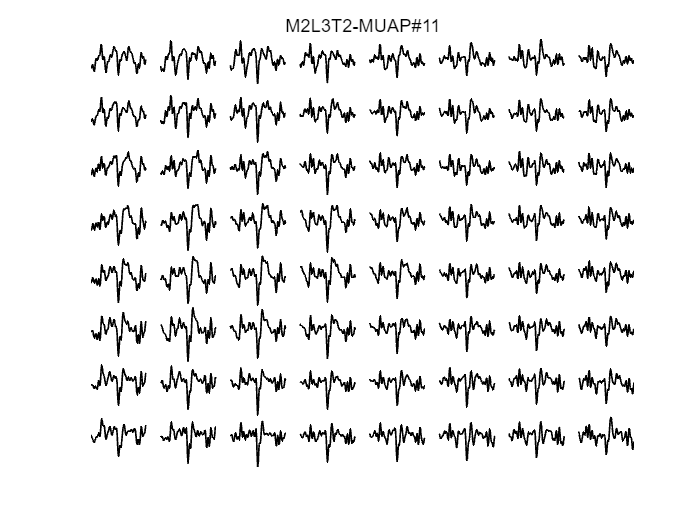

which2show=11;
clf;
muap_recon=muap_pca(muaparray{which2show},1);
% muap_recon=muaparray{which2show};
%去除明显有问题的电极
% for i=2:6 muap_recon{i,1}=[]; end
% muap_recon{3,4}=[];
% muap_recon{13,5}=[];

M=2;
figure;
plotArrayPotential(muap_recon,1,1);
tn4AP=['M' num2str(M) 'L' num2str(level) 'T' num2str(trial) '-MUAP#' num2str(which2show)];
title(tn4AP);

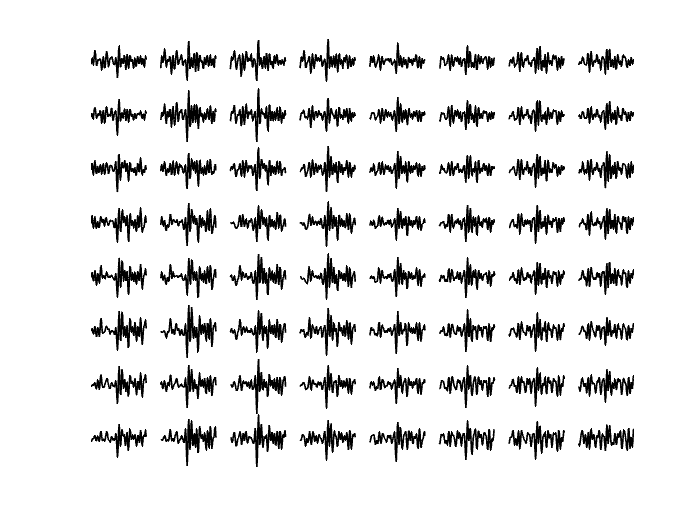

%求导
for i=1:8
    for j=1:8
        muap_diff{i,j}=diff(muap_recon{i,j});
    end
end
muap_diff=muap_pca(muap_diff,0.9);
figure;plotArrayPotential(muap_diff,1,1);

   ############ iEMG板块##############

fsampu = 2048; % iEMG、sEMG采样率
eafdata = importdata("Z:\Result\24-10-12iEMG-sEMG\M3L1T2.eaf"); % 读取eaf文件

提取放电串PT

muNum = max(eafdata.data(:,2)); % MU的个数
iPulses = {};
for mu = 1:muNum
    % iPulses就是这个eaf文件里分解得到的spike train，每个cell表示一个MU，里面的数字是该MU每次放电的时刻
    iPulses{mu} = round(eafdata.data(find(eafdata.data(:,2)==mu),1)'*fsampu); 
%     iPulses{mu} = iPulses{mu} -2*2048;
indicesToRemove = find(iPulses{mu}>9*2048); % 假设我们想去除索引为2和4的元素
iPulses{mu} = iPulses{mu}(~ismember(1:numel(iPulses{mu}), indicesToRemove)); % 去除指定索引的元素
% indicesToRemove = find(iPulses{mu}<0);
% iPulses{mu} = iPulses{mu}(~ismember(1:numel(iPulses{mu}), indicesToRemove)); % 去除指定索引的元素
end

绘制图像

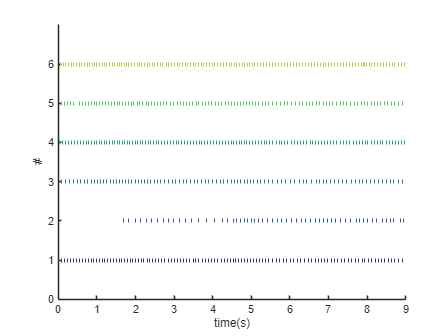

draw_PluseTime(iPulses,fsampu);

match=PulseMatch(old,iPulses,0.1,2048)

match = 5×10 table
    Pulses1    Pulses2    Sensitivity      RoA       Lag    Sensitivity_CC    FalseAlarm    Precision    Specificity      Acc  
    _______    _______    ___________    ________    ___    ______________    __________    _________    ___________    _______

      18          3         0.94681       0.55625      2       0.94681         0.92958       0.57419       0.99783      0.99767
      20          6         0.19685      0.089606    -21       0.11811         0.59124      0.084746       0.99468      0.99104
      22          5         0.39623      0.095588    284       0.49057         0.89024       0.10612       0.98561      0.98389
      23          1         0.47748       0.10729      9       0.47748         0.86848       0.12156       0.98744      0.98559
      30          4         0.49587      0.096154     12       0.49587         0.89184       0.10657        0.9835      0.98157


单独比较放电串

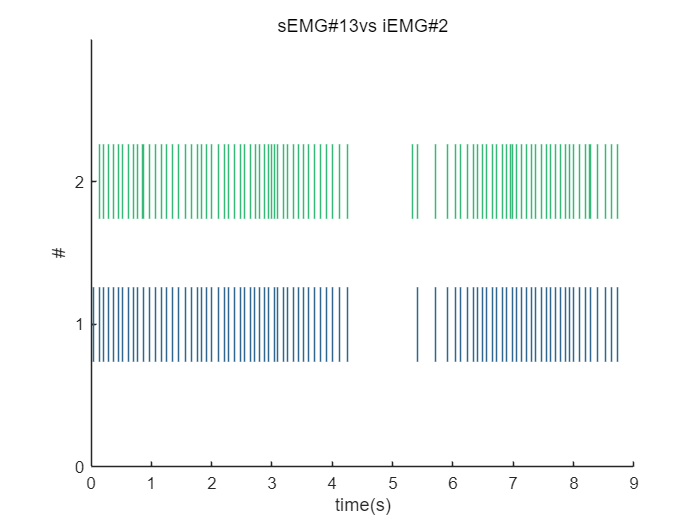

i=13;j=2;
compare{2}=old{i};
compare{1}=iPulses{j};
draw_PluseTime(compare,2048,1,2000,1,1);
title(['sEMG#' num2str(i) 'vs iEMG#' num2str(j)])

绘制手动修改后的MUST图

unwanted是不要的spiketrain

new是新的放电串cell

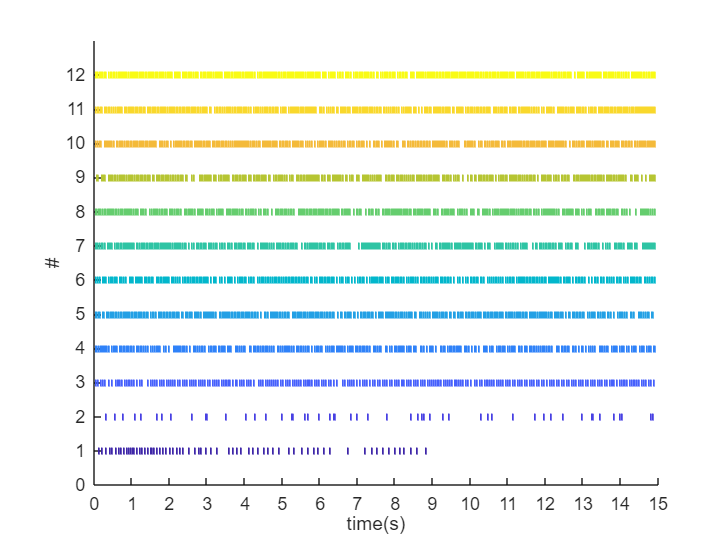

%初始化
i=1;
new=cell(0);
muapnew=cell(0);
W=[];
Ctx=[];
SIL=[];
Centroids=[];
%写入需要去除的muapt
unwanted=union(unwant,[]);
%得到去除后的muapt
for j=1:length(old)
    if find(unwanted==j)
        continue;
    end
    new{i}=old{j};
    muapnew{i}=muaparray{j};
    W(:,i)=decomps.W(:,j);
    Ctx(:,i)=decomps.Ctx(:,j);
    SIL(:,i)=decomps.SILs(:,j);
    Centroids(i,:)=decomps.Centroids(j,:);
    i=i+1;
end
%绘图
draw_PluseTime(new,fsamp,1);

% titlename=['KYM-M' num2str(M) 'L' num2str(L) 'T' num2str(T) '-' num2str(gn) '-selected-CKC'];
 % title(titlename);

 selected.MUPulses=new;
 selected.muaps=muapnew;
 selected.W=W;
 selected.SIL=SIL;
 selected.Ctx=Ctx;
 selected.unwanted=unwanted;
 % selected.data=data_sEMG;
 selected.datafilt=datafilt;
 selected.prohibitInd=decomps.prohibitInd;
 selected.Centroids=Centroids;
 selected.debugpara=decomps.debugpara;
 % %得到CoV数据
 % PT=selected.pulses;
 % for i=1:length(PT)
 %     isi{i}=diff(PT{i});
 %     CoV{i}=std(isi{i})/mean(isi{i});
 % end
 % selected.CoV=CoV;

 match=PulseMatch(selected.MUPulses,iPulses,0.1,2048)

函数或变量 'iPulses' 无法识别。

保存

% picture=['.\tmp\' titlename '.jpg'];
% saveas(gcf,picture);
% savename=['KYM-M' num2str(M) 'L' num2str(L) 'T' num2str(T)  '-selected-CKC'];
% filename=['.\tmp\' savename '.mat'];
% save( filename,    'selected');

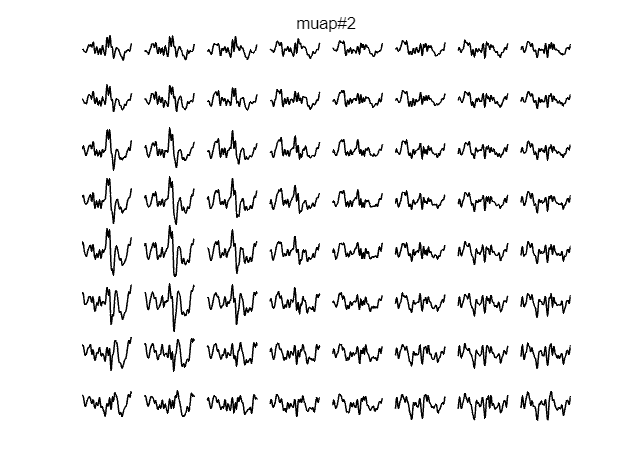

which2show=2;
clf;
plotArrayPotential(selected.muaps{which2show},1,1);
titlename=['muap#' int2str(which2show)];
title(titlename)

for k=1:1:length(selected.muaps)
tmpmuap=selected.muaps{k};
tmpmuap{1,1}=tmpmuap{2,1};
for i=1:12
    for j=1:5
        % tmpmuap{1,1}=zeros(1,50);
        difmuap{k}{i,j}=tmpmuap{i+1,j}-tmpmuap{i,j};
    end
end
end


clf;
which=3;
plotArrayPotential(difmuap{which},1,1);
